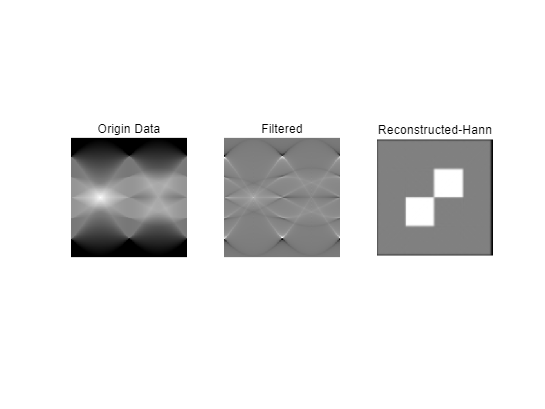

clf;
clear;

load("../materials/projection_data.mat");
[M,~] = size(proj);
N = 2*floor(M/(2*sqrt(2))); % size of output
r = r(3:182)*pi/180; % rad the angle

% check
% [check,H]=iradon(proj,r,'linear');
% figure;
% imshow(uint8(check),[]);

figure;
subplot(1,3,1);
imshow(proj,[]);title("Origin Data");

% Ramp Filter
width = max(64,2^nextpow2(2*M));
n = 0:(width/2);
filt_tmp = zeros(1,(width/2)+1);
filt_tmp(1) = 1/4;
filt_tmp(2:2:end) = -1./((pi*n(2:2:end)).^2);
filt_tmp = [filt_tmp filt_tmp(end-1:-1:2)]; 
filter = 2*real(fft(filt_tmp));
filter = filter(1:(width/2)+1);
w = 2*pi*(0:size(filter,2)-1)/width;

d = 1;
filter(2:end) = filter(2:end).*(1+cos(w(2:end)./d))/2; % HANN window
filter(w>pi*d) = 0;
filter = [filter'; filter(end-1:-1:2)'];

% Filter Projection
proj(length(filter),1)=0; % zero padding
proj_fft = fft(proj);
proj_filtered = zeros(width,180);
for i = 1:180
    proj_filtered(:,i) = proj_fft(:,i).*filter;
end
proj_ifft = real(ifft(proj_filtered));
proj_ifft(M+1:end,:) = []; % resize

subplot(1,3,2);
imshow(proj_ifft,[]);title('Filtered');

% FBP
fbp = zeros(N);
costheta = cos(r);
sintheta = sin(r);

center = floor((N + 1)/2);
x = (1:N)-1-center+1;
x = repmat(x, N, 1);

y = (N:-1:1).'-N+center-1;
y = repmat(y, 1, N);

for i = 1:180
    tmp = (1:M) - ceil(M/2);
    t = x.*costheta(i) + y.*sintheta(i);
    projContrib = interp1(tmp,proj_ifft(:,i),t(:),'linear');
    fbp = fbp + reshape(projContrib,N,N);
end
fbp = fbp*pi/180/2;

subplot(1,3,3);
imshow(uint8(fbp),[]);title('Reconstructed-Hann');